# **Matlab 编程**

**MATLAB的代码两种执行方式：交互式的命令执行方式、程序执行方式**

# **1. m 文件**

        m文件是MATLAB程序的脚本文件(Script)，是一段MATLAB程序。便于程序的编辑、调式、运行和保存，并可以编译。可在MATLAB的程序编辑器中编写，也可在其他的文本编辑器中编写，以“.m”为扩展名加以存储.

**1.1 m 文件的建立与打开**

% 建立新的 m文件

**1.2 m 文件的分类**

% matlab中 m文件分为两种，分别是脚本文件和函数文件

% 脚本文件实际上是个命令的集合，可以认为他是命令行的改良版，方便我们去编写命令
% 函数文件则是声明了一个函数，是一个代码块，方便我们调用

% 二者区别
% 脚本没有输入参数，也没有返回参数，而函数则是和其他语言一样，有输出参数，也可带有返回参数
% 脚本可以直接运行，而函数则需要调用才能运行

**1.3 m 文件的执行**

首先确认M文件处于当前工作目录下，在命令行中输入M文件的名字回车运行，或者点击M文件编辑器按钮，F5快捷键保存并运行。

**    ex1:编写计算圆柱体积的函数和脚本**

% 脚本文件：输入脚本文件名执行或直接按 F5执行  (test111.m)
% 函数文件：在脚本中调用执行

# **2. 三种程序结构**

**2.1 顺序结构**

% 数据的输入 input()
a = input('请输入数值a：')
A = input('请输入矩阵A：')

% 数据的输出 disp()
disp(A)

% 程序的暂停 pause(senconds)
pause(5)


**    ex2:编写求解一元二次方程的函数 (func2.m)**

**                                                    ax^2+bx+c = 0**

**2.2 选择结构 **

**  - if 结构**

% if-else 语句
test1 = input('请输入测试数据1：')
if test1 >= 0
    disp('test1 为非负数')
else
    disp('test1 为负数')
end


% if-elseif-else 语句
test2 = input('请输入测试数据2：')
if test2 >= 3 && test2<6
    disp('test2 一定比2大但比6小')
elseif test2 >=6
    disp('test2 一定比5大')
else 
    disp('test2 一定比3小')
end


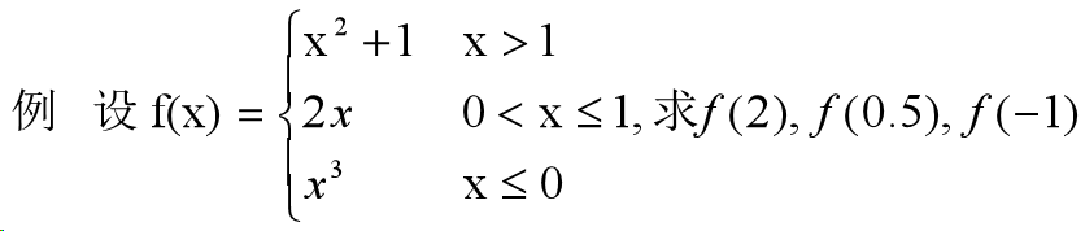

**- switch 结构**

switch item
    case (condition1)
        {commands1}
    case (condition2)
        {commands2}
    otherwise
        {commands3}
end

对于指标item，若满足对应的condition，则执行对应的命令串{commands}.

% switch 
price = input('请输入测试数据price:')
switch price
    case price<=200 && price >= 100
        disp(1)
    case price>=400
        disp(2)
    otherwise
        disp('error')
end

**2.3  循环结构 (重要）**

% for while
% break 和 continue  (只能用在循环结构中)

- **for 语句** -> 适用于事先能确定循环次数的循环结构

% Instance : 求阶乘
res = 1;
for i = 1:1:5 % start : walk :end
    res = res * i;
end
res

disp('*****************分界线*************')


% for循环需要注意的地方
for k=[1 2 3 5]
    k
end

disp('*****************分界线*************')

for k=[1 2 3 5]
    k
    k=20
end

disp('*****************分界线*************')

n = 10;
for k = 1:1:n
    n = 5;
    k
end
% 注意：循环在一开始进入的时候，循环变量就已经确定，不会再随着
% 循环体内部的改变而变化。

disp('*****************分界线*************')

for k=[1 2 3 5]
end
disp(k)
% 注意：最终的值就是循环体向量中最后的值

disp('*****************分界线*************')
for k=[]
    disp('for循环已执行')
end
% 注意：循环向量为空的时候，循环一次也不会执行



% for循环的循环变量为矩阵时(更一般的形式)   按列循环
disp('*****************分界线*************')
sum = 0;
a = [1,2,3 ; 4,5,6 ; 7,8,9 ; 10,11,12];
b = [1 2 3;
     4 5 6;];
for k = b
    k
end
disp(b)
disp('*****************分界线*************')
for k = a
    k
end
disp(a)
disp('*****************分界线*************')

%ex : f = (e.^(-0.5*x))*sin(x+pi/6)  求0~3pi积分值sum

% f = @(x) exp(-0.5*x).*sin(x+pi/6)
% 
% integral(f,0,3*pi)
% 
% getIntegral(0,3*pi)
% 
% disp('*****************分界线*************')



- **while语句**

a=5;
n=1;
sum=1;

% 阶乘
while (n<=a)
    sum = sum*n;
    n=n+1;
end

sum

disp('*****************分界线*************')

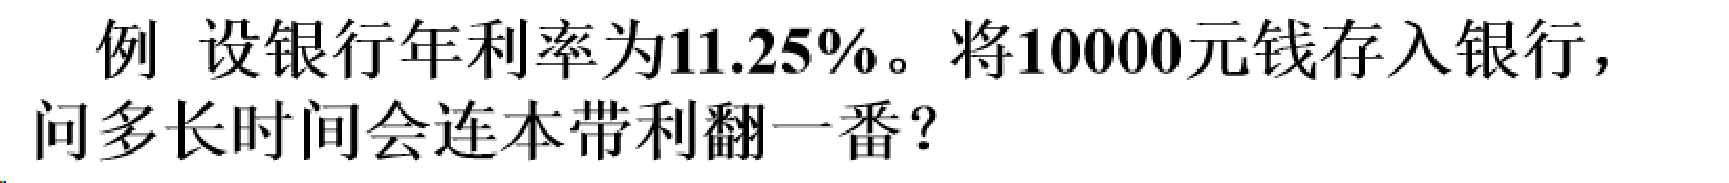

- **break 和 continue**

% break: 强行跳出循环, 跳出一整层循环
% continue: 强行跳出本次循环并进入下一次, 即跳出一次循环 

for p=1:10
    if p==5
        % break
        continue
    end
    disp(p)
    
end


**    - 循环嵌套**

% for 循环的嵌套

% ex1
sum=0;
for k=1:1:10
    sum=sum+k;
end
disp(sum)
disp('*****************分界线*************')

% ex2
sum=0;
for k=1:1:10

    for j=1:1:10
        sum=sum+j;
    end

end
disp(sum)
disp('*****************分界线*************')  

% ex3
sum=0;
for k1=1:1:10

    for k2=k1:1:10
        sum = sum + k2;
    end
    disp(sum)
    sum = 0;
end
disp('*****************分界线*************')   


%循环嵌套相关题目
% 求解  1！+2！+3！+4！+5！  +...+ n!
c = 5;
sum = 0;

for k1=1:1:c
    temp = 1;
    for k2=1:1:k1
        temp = temp*k2;
    end
    sum = sum + temp;
end

disp(sum)

# **3. 函数文件**

**    - 函数文件的基本结构**

% 由function和end引导，包含输出和输入
% 说明：函数文件名与函数名可以不相同

% 见test1.m

**    - 函数调用**

% [输出参数表] = 函数名[输入参数]   
% 形参、实参
% 注意：参数出现的顺序、个数要与定义时的相同。

  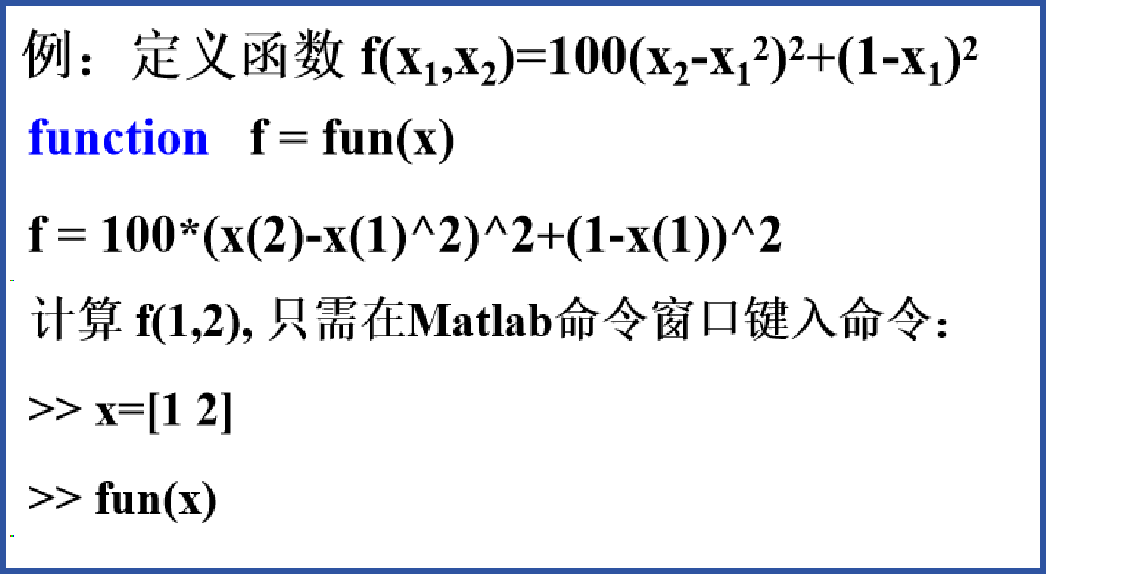

**  - 递归**

% 即一个函数的返回值是函数本身
% ex 利用递归实现阶乘的计算
res = getFact(5)
disp('*****************分界线*************')   
% 见getFact.m

**    - 函数参数**

% matlab中，函数参数的个数具有可变性
% matlab的两个预定义变量
% nargin:函数的输入变量个数
% nargout: 函数的输出变量个数
a=changePara(5)
[b,c]=changePara(7,10)
d=changePara(9,5)
disp('*****************分界线*************')   
% 见changePara.m

**    - 变量的作用域**

% 全局变量global 以及局部变量local
% global 作用域为整个函数空间，所有函数都可以对他进行存取和修改
% global可以用来函数间的信息传递

% 不提倡使用 global

# **4. MATLAB常用内部函数**

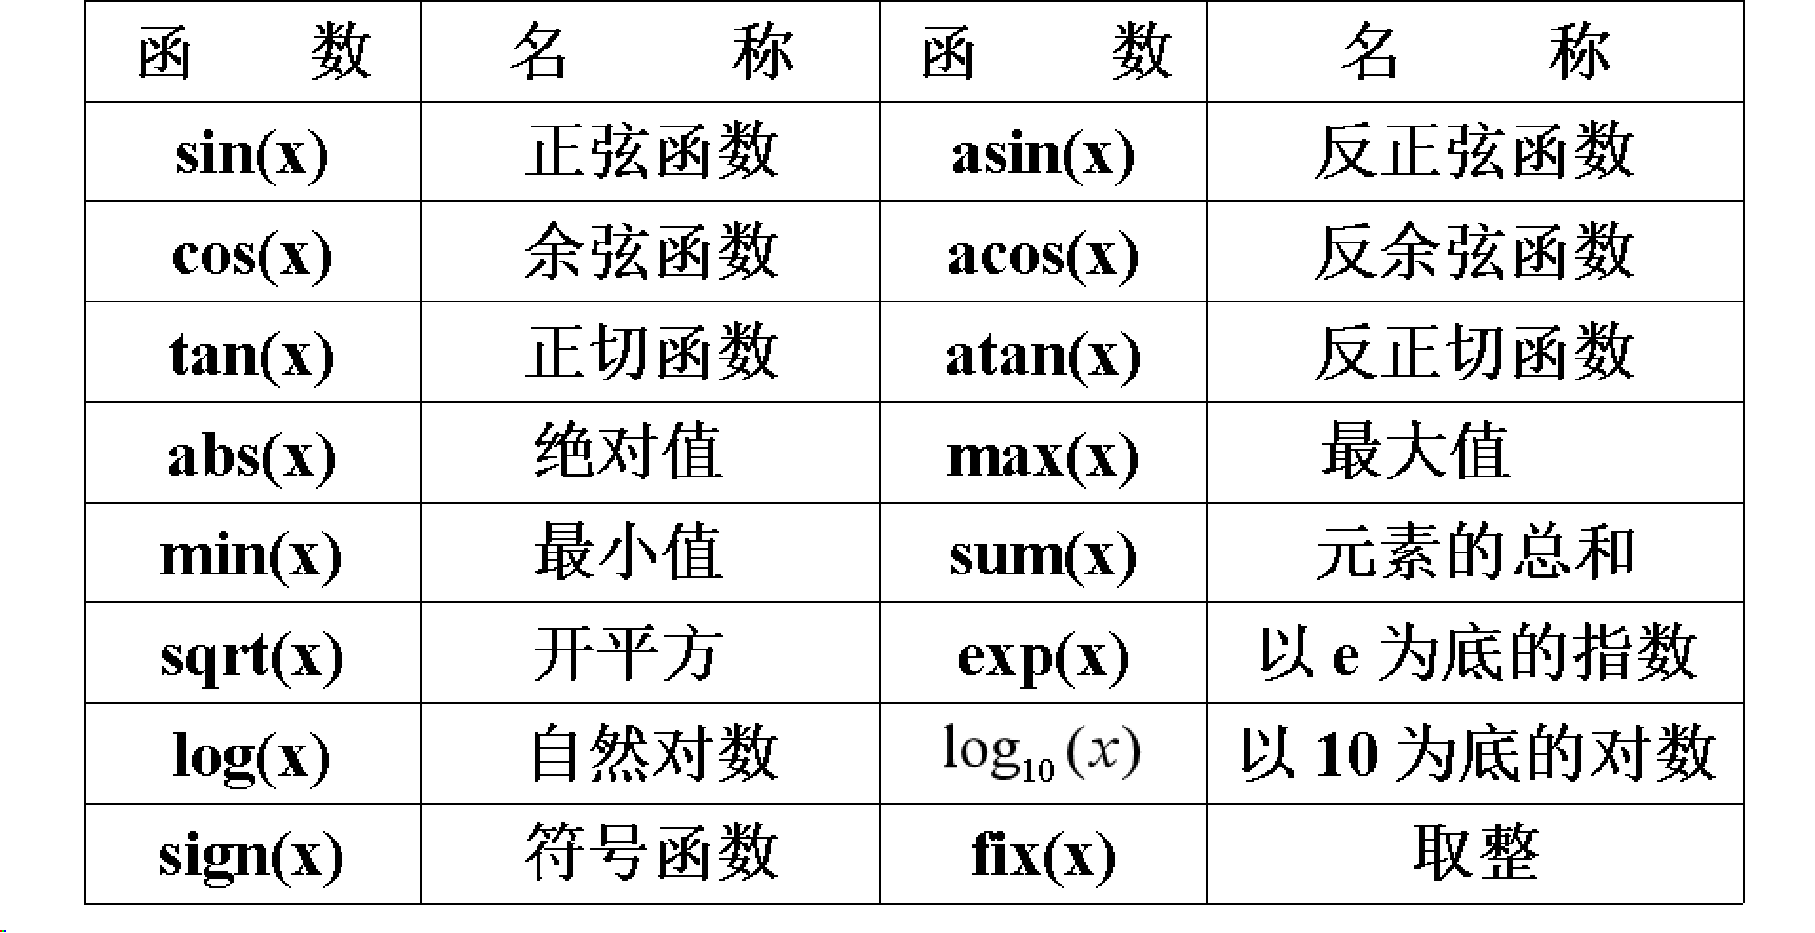

x = sqrt(7)-2i;
y = exp(pi/2);
z=(5+cosd(47))/(1+abs(x-y))
cos(47*pi/180)
cosd(47)
log(10)  %ln
log10(100)
pow2(16)
gcd(12,82)
factorial(5)

# **5. 特殊函数**

**    为什么要有子函数、内联函数、匿名函数？**

**    - 子函数**

% 主函数 Primary function
% 子函数 Subfunction
% 子函数类似于其他编程语言中的函数嵌套中的内层函数
% funcWithSub(6,4,9)
% 见 funcWithSub.m

**    - 内联函数**

% 以字符串形式存在的函数表达式可以通过 inline 函数转化成内联函数。
a = '(x+y+z)^3';
f1 = inline(a)
f1(1,2,3)
disp('*****************分界线*************')   

**    - 匿名函数 一行函数**

% 基本格式如下

% 匿名函数名 = @（匿名函数输入参数） 匿名函数表达式  ex1
% 或 匿名函数名 = @ 函数名  ex2

% ex1
funcNone = @(a) a^2+3*a
funcNone(2)
disp('*****************分界线*************') 

% ex2
% s = @sin
% s(pi/2)
% disp('*****************分界线*************') 

# **6. 程序的调试与优化**

**    - 程序调试**

% help debug
% 常用的有 
% dbstop  设置函数断点
% dbclear 清除断点
% dbcont 从断点处执行
% dbquit 退出debug模式

% 步进：运行一条语句，但不进入函数  F10
% 步入：单步运行，遇到函数进入函数，仍然单步运行  F11

**    - 程序性能分析与优化**

% 预分配：尽管MATLAB数组无须定义大小，但经常改变数组大小会影响速度，
% 采取一些分配方法可提高运算速度

% 较差的程序：                                             
v(1)=2;                                                         
for i=2:100                                                   
    v(i)=v(i-1)^0.5                   
end              
% 较好的程序：
v=2*ones(1,100);
for i=2:100                                                   
    v(i)=v(i-1)^0.5                   
end 
                                          
